# Localize mobile robot with a particle filter

Copyright (C) 1993-2018, by Peter I. Corke, http://www.petercorke.com

Our localization system requires a number of components:

- a vehicle

- a map that defines the positions of some known landmarks in the world

- a sensor, a range-bearing sensor in this case

- a localization filter, specifically the Monte-Carlo style "particle filter"

## Creating the vehicle model

First we define the covariance of the vehicles's odometry which reports distance travelled and change in heading angle

V = diag([0.1, 1*pi/180].^2);

 then use this to create an instance of a Bicycle class, a vehicle with car-like (Ackerman) steering

veh = Bicycle(V);

and then add a "driver" to move it between random waypoints in a square region with dimensions from -10 to +10

veh.add_driver( RandomPath(10) );

## Creating the map

The map covers a square region with dimensions from  -10 to +10 and contains 20 randomly placed landmarks

map = LandmarkMap(20, 10)

 
map = 
LandmarkMap object
  20 landmarks    
  dimension 10.0  


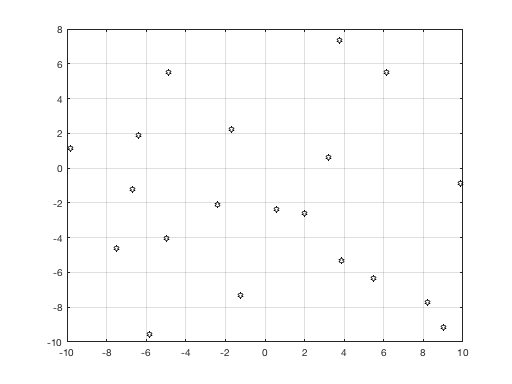

plot(map)

## Creating the sensor model

We firstly define the covariance of the sensor measurements which report distance and bearing angle

W = diag([0.1, 1*pi/180].^2);

and then use this to create an instance of the `Sensor` class.

sensor = RangeBearingSensor(veh, map, 'covar', W, 'animate');

Note that the sensor is mounted on the moving robot and observes the features in the world so it is connected to the already created Vehicle and Map objects.

## Create the filter.  

The particle filter requires a likelihood function that maps  the error between expected and actual sensor observation to a weight.  The Toolbox  uses a 2D Gaussian for this and we need to describe it by a covariance matrix

L = diag([0.1 0.1]);

The filter also needs a noise model to "drift" the particles at each step, that is the hypotheses are randomly moved to model the effect of uncertainty in the vehicle's pose

Q = diag([0.1, 0.1, 1*pi/180]).^2;

the values of this matrix should be consistent with the vehicle uncertainty  model V given above.

Now we create an instance of the particle filter class

pf = ParticleFilter(veh, sensor, Q, L, 1000);

and connect it to the vehicle and the sensor and give estimates of the vehicle and sensor covariance (we never know this is practice).  The last argument is the number of particles that will be used.  Each particle represents a hypothesis about the vehicle's pose and a weight (or likeliness).

Now we will run the filter for 200 time steps.  At each step the vehicle moves, reports its odometry and the sensor measurements and the filter updates its estimate of the vehicle's pose.  

The green dots represent the particles.  We see that initially the pose hypotheses are very spread out, but soon start to cluster around the actual pose of the robot.  The pose is 3D (x,y, theta) so if you rotate the graph while the simulation is running you can see the theta dimension as well.

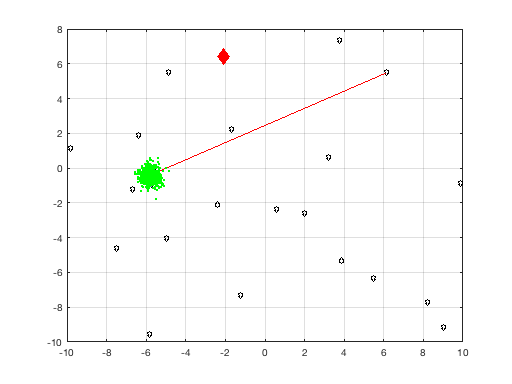

pf.run(200);

all the results of the simulation are stored within the ParticleFilter object

First let's plot the map

clf; map.plot()

and then overlay the path actually taken by the vehicle

veh.plot_xy('b');

and then overlay the path estimated by the filter

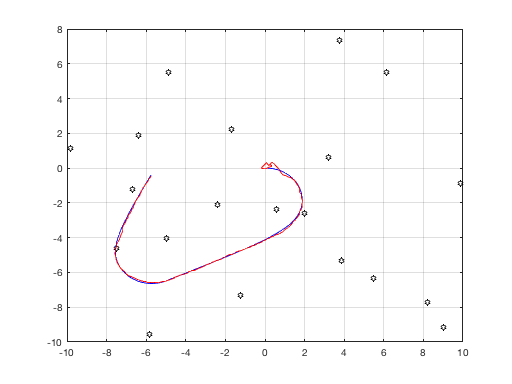

pf.plot_xy('r');

which we see are pretty close once the filter gets going, the initial estimates (when the particles are spread widely) are not so good.

The uncertainty of the estimate is related to the spread of the particles and we can plot that

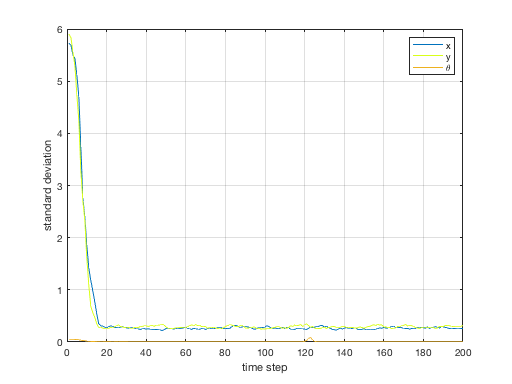

figure; plot(pf.std); xlabel('time step'); ylabel('standard deviation'); legend('x', 'y', '\theta'); grid